# Robot Navigation Project - View Sequence Data

This dataset was obtained from the UCI Machine Learning Repository. 

You can find more information on this dataset here:

[https://archive.ics.uci.edu/ml/datasets/Wall-Following+Robot+Navigation+Data](https://archive.ics.uci.edu/ml/datasets/Wall-Following+Robot+Navigation+Data)

## Load the sensor data

There are four .csv files that each contain 3 variables.

- `front`: Sensor reading from the front of the robot

- `left`: Sensor reading from the left of the robot

- `direction`: The action the robot should take at this time step. At any point, the robot can either move forward, turn slightly to the left, turn slightly to the right, or turn sharply to the right

robods = signalDatastore("../data/robotdata", "SignalVariableNames", ["front" "left"], "ReadOutputOrientation", "row");
transds = transform(robods, @prepsig);
sigdata = readall(transds);

labelds = signalDatastore("../data/robotdata", "SignalVariableNames", "direction")

labelds =   signalDatastore with properties:

                       Files:{
                             ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata\turn1.csv';
                             ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata\turn2.csv';
                             ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata\turn3.csv'
                              ... and 1 more
                             }
                     Folders: {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata'}
    AlternateFileSystemRoots: [0×0 string]
                    ReadSize: 1
         SignalVariableNames: "direction"
       ReadOutputOrientation: "column"


transds = transform(labelds, @preplabel);
labels = readall(transds);

Create variable for the sample rate. The sensor readings were sampled at a rate of 9 samples per second.

fs = 9;

## Display data

Display the first feature of the sequence data.

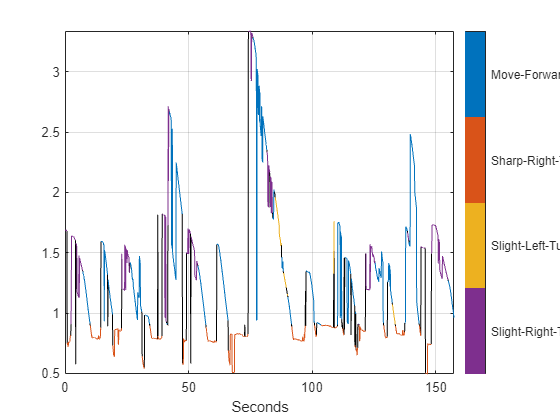

msk = signalMask(labels{1}, "SampleRate", fs);
plotsigroi(msk, sigdata{1}(1, :))

Display the second feature.

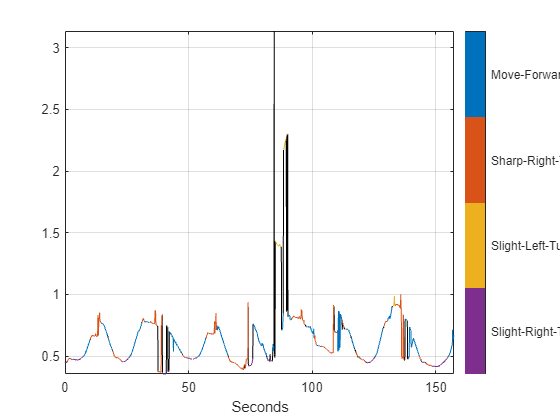

plotsigroi(msk, sigdata{1}(2, :))

Format the signals for training

function sigout = prepsig(sig)
    sigmatrix = cell2mat(sig);
    sigtranspose = sigmatrix';
    sigout = {sigtranspose};
end

Format the labels for training

function [labelout] = preplabel(label)
    labelcat = categorical(label);
    labeltranspose = labelcat';
    labelout = {labeltranspose};
end